% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 15;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_1 = load('MAT Files/Growth_Medium_2024-06-05_3_100_300.mat');
data_2 = load('MAT Files/Growth_Medium_2024-06-05_5_100_290.mat');
data_3 = load('MAT Files/Growth_Medium_2024-06-05_3.5_100_280.mat');
data_4 = load('MAT Files/Growth_Medium_2024-06-05_3.8_100_270.mat');
data_5 = load('MAT Files/Growth_Medium_2024-06-05_1.5_100_260.mat');
data_6 = load('MAT Files/Growth_Medium_2024-06-05_3.5_100_250.mat');
data_7 = load('MAT Files/Growth_Medium_2024-06-05_3.5_100_240.mat');
data_8 = load('MAT Files/Growth_Medium_2024-06-05_4_100_230.mat');
data_9 = load('MAT Files/Growth_Medium_2024-06-05_4.5_100_220.mat');

Growth_300 = data_1.tempdata;
Growth_290 = data_2.tempdata;
Growth_280 = data_3.tempdata;
Growth_270 = data_4.tempdata;
Growth_260 = data_5.tempdata;
Growth_250 = data_6.tempdata;
Growth_240 = data_7.tempdata;
Growth_230 = data_8.tempdata;
Growth_220 = data_9.tempdata;

% Configuring and plotting unprocessed data

wavenumber = Growth_300(1,:);

% trimming standard sample data to these WN's
t1 = 200;
t2 = 1800;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
Growth_300(:, Growth_300(1, :) <= t1) = [];
Growth_300(:, Growth_300(1, :) >= t2) = [];
Growth_290(:, Growth_290(1, :) <= t1) = [];
Growth_290(:, Growth_290(1, :) >= t2) = [];
Growth_280(:, Growth_280(1, :) <= t1) = [];
Growth_280(:, Growth_280(1, :) >= t2) = [];
Growth_270(:, Growth_270(1, :) <= t1) = [];
Growth_270(:, Growth_270(1, :) >= t2) = [];
Growth_260(:, Growth_260(1, :) <= t1) = [];
Growth_260(:, Growth_260(1, :) >= t2) = [];
Growth_250(:, Growth_250(1, :) <= t1) = [];
Growth_250(:, Growth_250(1, :) >= t2) = [];
Growth_240(:, Growth_240(1, :) <= t1) = [];
Growth_240(:, Growth_240(1, :) >= t2) = [];
Growth_230(:, Growth_230(1, :) <= t1) = [];
Growth_230(:, Growth_230(1, :) >= t2) = [];
Growth_220(:, Growth_220(1, :) <= t1) = [];
Growth_220(:, Growth_220(1, :) >= t2) = [];

Growth_300 = Growth_300(2:end,:);
Growth_290 = Growth_290(2:end,:);
Growth_280 = Growth_280(2:end,:);
Growth_270 = Growth_270(2:end,:);
Growth_260 = Growth_260(2:end,:);
Growth_250 = Growth_250(2:end,:);
Growth_240 = Growth_240(2:end,:);
Growth_230 = Growth_230(2:end,:);
Growth_220 = Growth_220(2:end,:);

poly1 = load('MAT Files/Polystyrene_2024-06-05_2_200.mat');
poly = mean(poly1.tempdata(2:end,:));

Si1 = load('MAT Files/Silicon_2024-06-05_0.6_200');
Si = mean(Si1.tempdata(2:end,:));

std_int = [poly1.tempdata(1, :) ; poly ; Si];
std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

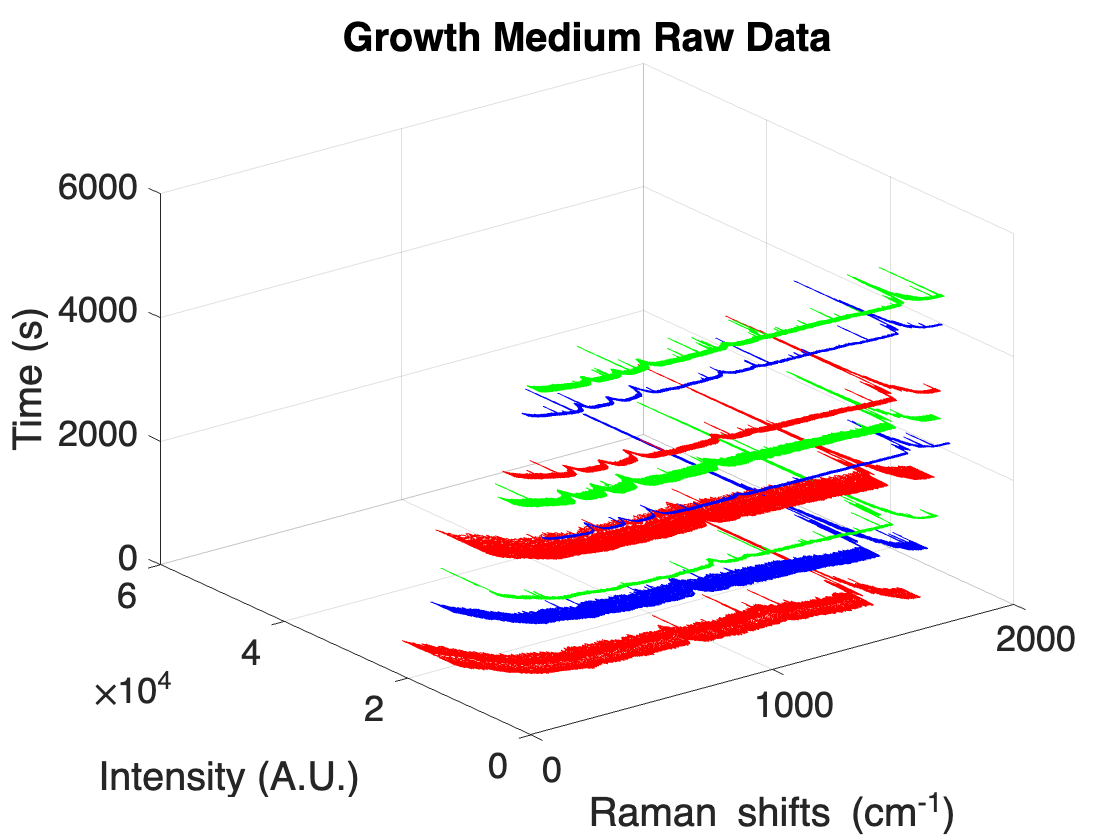

% Defining time of sample collection

time = [0, 840, 1440, 2040, 2700, 3030, 3480, 4560, 5040];

% Plotting unprocessed data

% Plotting unprocessed data in 3D
fig1 = figure;
ax1 = axes(fig1);
hold on;
grid on;

% Plot each spectrum with corresponding time value
plot3(wavenumber, Growth_300, time(1) * ones(size(wavenumber)), 'r-');
plot3(wavenumber, Growth_290, time(2) * ones(size(wavenumber)), 'b-');
plot3(wavenumber, Growth_280, time(3) * ones(size(wavenumber)), 'g-');
plot3(wavenumber, Growth_270, time(4) * ones(size(wavenumber)), 'r-');
plot3(wavenumber, Growth_260, time(5) * ones(size(wavenumber)), 'b-');
plot3(wavenumber, Growth_250, time(6) * ones(size(wavenumber)), 'g-');
plot3(wavenumber, Growth_240, time(7) * ones(size(wavenumber)), 'r-');
plot3(wavenumber, Growth_230, time(8) * ones(size(wavenumber)), 'b-');
plot3(wavenumber, Growth_220, time(9) * ones(size(wavenumber)), 'g-');

xlabel('Raman shifts (cm^{-1})');
ylabel('Intensity (A.U.)');
zlabel('Time (s)');
title('Growth Medium Raw Data');
ax1.FontSize = 18;

% Adjust view angle for better 3D perception
view(3); % Default 3D view

% Add lighting for better depth perception
camlight;
lighting gouraud;

hold off;

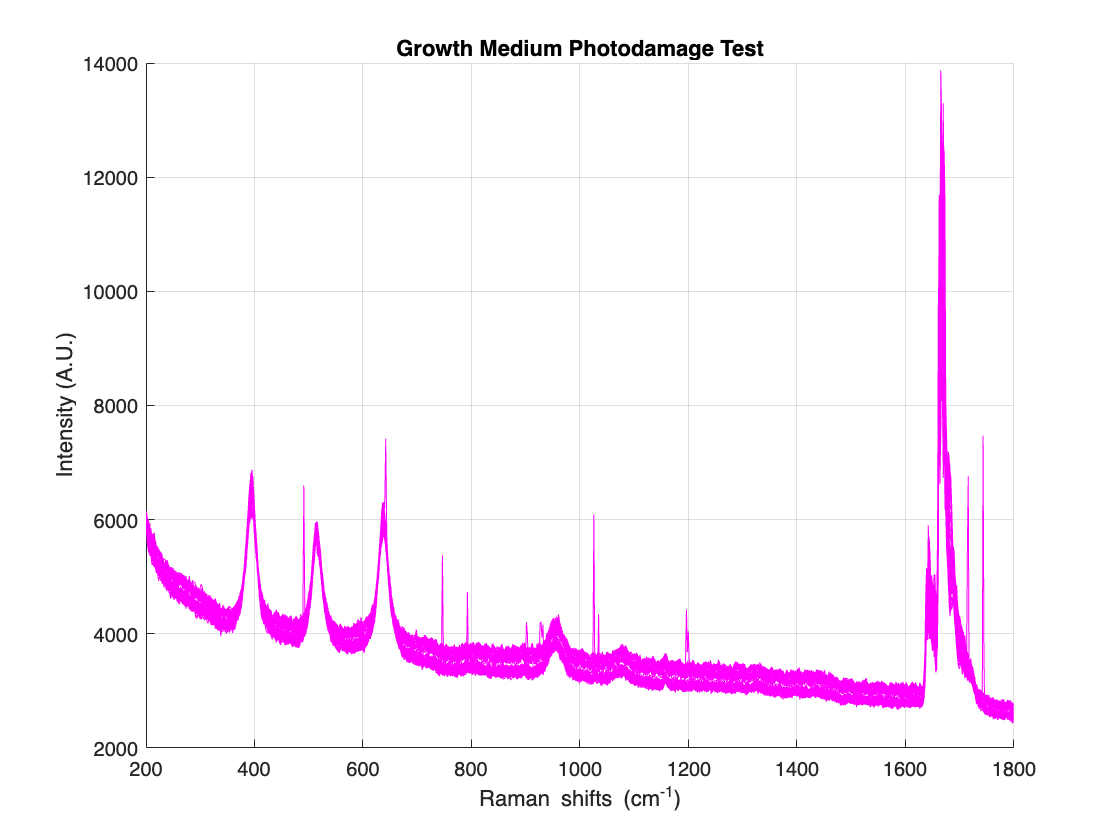

figure;
hold on;
grid on;
% plot(wavenumber, Growth_300, '-b');
% plot(wavenumber, Growth_290, '-r');
% plot(wavenumber, Growth_280, '-g');
% plot(wavenumber, Growth_270, '-c');
plot(wavenumber, Growth_260, '-m');
% plot(wavenumber, Growth_250, '-k');
% plot(wavenumber, Growth_240, '-y');
% plot(wavenumber, Growth_230, '-');
% plot(wavenumber, Growth_220, '-');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Photodamage Test');
hold off;

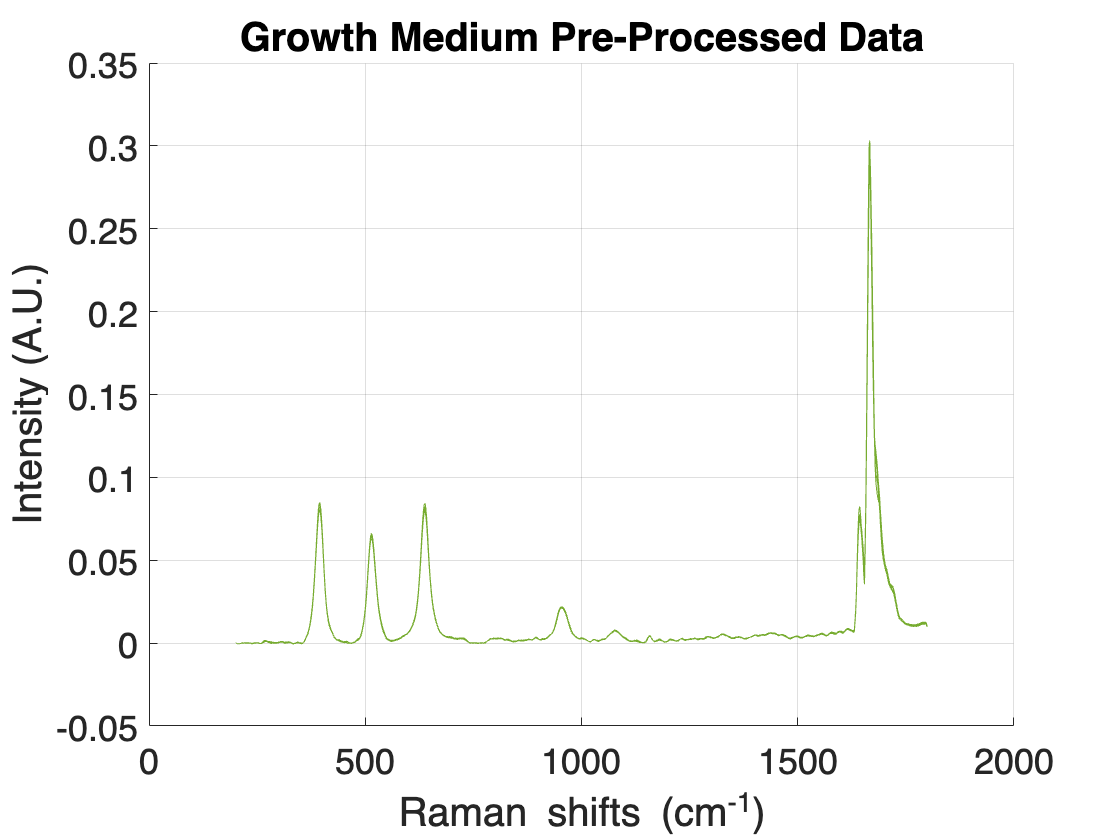

pro_Growth_300 = apply(Growth_300, [6,1,8,2,5,6,7]);
pro_Growth_290 = apply(Growth_290, [6,1,8,2,5,6,7]);
pro_Growth_280 = apply(Growth_280, [6,1,8,2,5,6,7]);
pro_Growth_270 = apply(Growth_270, [6,1,8,2,5,6,7]);
pro_Growth_260 = apply(Growth_260, [6,1,8,2,5,6,7]);
pro_Growth_250 = apply(Growth_250, [6,1,8,2,5,6,7]);
pro_Growth_240 = apply(Growth_240, [6,1,8,2,5,6,7]);
pro_Growth_230 = apply(Growth_230, [6,1,8,2,5,6,7]);
pro_Growth_220 = apply(Growth_220, [6,1,8,2,5,6,7]);

% Define a colormap with distinct colors
colors = [
    [0, 0.4470, 0.7410];    % Blue
    [0.8500, 0.3250, 0.0980]; % Red
    [0.9290, 0.6940, 0.1250]; % Yellow
    [0.4940, 0.1840, 0.5560]; % Purple
    [0.4660, 0.6740, 0.1880]; % Green
    [0.3010, 0.7450, 0.9330]; % Cyan
    [0.6350, 0.0780, 0.1840]; % Dark Red
    [0.5, 0.5, 0.5];         % Gray
    [1, 0.6, 0];             % Orange
];

% Example of how to use these colors in your plot
fig2 = figure;
ax2 = axes(fig2);
hold on;
grid on;
% plot(ax2, wavenumber, pro_Growth_300, '-', 'Color', colors(1,:));
% plot(ax2, wavenumber, pro_Growth_290, '-', 'Color', colors(2,:));
% plot(ax2, wavenumber, pro_Growth_280, '-', 'Color', colors(3,:));
% plot(ax2, wavenumber, pro_Growth_270, '-', 'Color', colors(4,:));
plot(ax2, wavenumber, pro_Growth_260, '-', 'Color', colors(5,:));
% plot(ax2, wavenumber, pro_Growth_250, '-', 'Color', colors(6,:));
% plot(ax2, wavenumber, pro_Growth_240, '-', 'Color', colors(7,:));
% plot(ax2, wavenumber, pro_Growth_230, '-', 'Color', colors(8,:));
% plot(ax2, wavenumber, pro_Growth_220, '-', 'Color', colors(9,:));
xlabel(ax2, 'Raman shifts (cm^{-1})')
ylabel(ax2, 'Intensity (A.U.)')
title('Growth Medium Pre-Processed Data')
ax2.FontSize = 18;
hold off;

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end

